## Q2 - part c | Output Error

clc; clear;

%%

load HW5_question2

u1 = Z1.u;
y1 = Z1.y;

u2 = Z2.u;
y2 = Z2.y;

u3 = Z3.u;
y3 = Z3.y;

u1_val = u1(601:end);
y1_val = y1(601:end);

u2_val = u2(601:end);
y2_val = y2(601:end);

u3_val = u1(601:end);
y3_val = y1(601:end);

u1 = u1(1:600);
y1 = y1(1:600);

u2 = u2(1:600);
y2 = y2(1:600);

u3 = u3(1:600);
y3 = y3(1:600);


### System I

%%

% System Z1 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System I Identification Begins:------------------------------\n")

>>> System I Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data1 = iddata(y1,u1,Ts);


%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    try
        sys = oe(data1, [na nb nk]);
        oe_y_hat_1 = lsim(sys, u1, t);
    catch
        break
    end

    [r2_oe, mse_oe] = rSQR(y1, oe_y_hat_1);

    error = y1 - oe_y_hat_1;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.599900 | MSE=33.478625 | var=33.590593 | s_hat=20087.174802 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.605320 | MSE=33.025154 | var=33.246800 | s_hat=19815.092682 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.920165 | MSE=6.680286 | var=6.747763 | s_hat=4008.171478 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.920558 | MSE=6.647359 | var=6.737189 | s_hat=3988.415641 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.921038 | MSE=6.607203 | var=6.719189 | s_hat=3964.321786 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.539485 | MSE=38.533901 | var=39.320307 | s_hat=23120.340427 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.921487 | MSE=6.569654 | var=6.726608 | s_hat=3941.792349 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.921499 | MSE=6.568660 | var=6.748623 | s_hat=3941.196079 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.923587 | MSE=6.393946 | var=6.591697 | s_hat=3836.367592 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.922592 | MSE=6.477194 | var=6.700545 | s_hat=3886.316323 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.925306 | MSE=6.250052 | var=6.487943 | s_hat=3750.031169 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.924866 | MSE=6.286893 | var=6.548846 | s_hat=3772.135543 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.921562 | MSE=6.563391 | var=6.860687 | s_hat=3938.034444 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.925055 | MSE=6.271090 | var=6.578066 | s_hat=3762.653991 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.921360 | MSE=6.580254 | var=6.926583 | s_hat=3948.152211 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.924669 | MSE=6.303376 | var=6.658495 | s_hat=3782.025419 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.922509 | MSE=6.484115 | var=6.873620 | s_hat=3890.468986 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.915164 | MSE=7.098740 | var=7.551851 | s_hat=4259.243979 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.926875 | MSE=6.118769 | var=6.532493 | s_hat=3671.261108 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.925904 | MSE=6.200043 | var=6.642903 | s_hat=3720.025920 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.928902 | MSE=5.949174 | var=6.396961 | s_hat=3569.504220 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=-2.585662 | MSE=300.032734 | var=323.776331 | s_hat=180019.640245 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.928887 | MSE=5.950470 | var=6.444553 | s_hat=3570.282170 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.923298 | MSE=6.418112 | var=6.976208 | s_hat=3850.867018 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.926228 | MSE=6.172925 | var=6.734100 | s_hat=3703.755228 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.928232 | MSE=6.005197 | var=6.575033 | s_hat=3603.118137 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.928168 | MSE=6.010551 | var=6.605001 | s_hat=3606.330685 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.924585 | MSE=6.310441 | var=6.960045 | s_hat=3786.264485 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.928960 | MSE=5.944306 | var=6.580413 | s_hat=3566.583838 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.916095 | MSE=7.020774 | var=7.800860 | s_hat=4212.464563 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.922652 | MSE=6.472133 | var=7.217992 | s_hat=3883.279587 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.864667 | MSE=11.324071 | var=12.676199 | s_hat=6794.442430 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.913570 | MSE=7.232086 | var=8.125939 | s_hat=4339.251498 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.928909 | MSE=5.948581 | var=6.708926 | s_hat=3569.148504 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.841637 | MSE=13.251135 | var=15.001285 | s_hat=7950.681130 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.862850 | MSE=11.476091 | var=13.041012 | s_hat=6885.654337 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.923538 | MSE=6.397995 | var=7.298093 | s_hat=3838.796872 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.928346 | MSE=5.995668 | var=6.865269 | s_hat=3597.400911 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.927716 | MSE=6.048410 | var=6.952196 | s_hat=3629.046284 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.627259 | MSE=31.189343 | var=35.987703 | s_hat=18713.605571 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.851248 | MSE=12.446945 | var=14.417311 | s_hat=7468.167071 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.874388 | MSE=10.510631 | var=12.221664 | s_hat=6306.378685 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.861442 | MSE=11.593907 | var=13.533743 | s_hat=6956.344073 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.312501 | MSE=57.526957 | var=67.414402 | s_hat=34516.173905 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.920909 | MSE=6.617968 | var=7.785844 | s_hat=3970.780510 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=-1.554671 | MSE=213.763860 | var=252.477000 | s_hat=128258.315823 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.931480 | MSE=5.733457 | var=6.798565 | s_hat=3440.073924 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.900337 | MSE=8.339373 | var=9.927826 | s_hat=5003.624062 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.878801 | MSE=10.141416 | var=12.121214 | s_hat=6084.849617 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.729371 | MSE=22.645048 | var=27.174058 | s_hat=13587.028918 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.857815 | MSE=11.897459 | var=14.334288 | s_hat=7138.475530 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.695742 | MSE=25.459040 | var=30.797225 | s_hat=15275.423764 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.927481 | MSE=6.068079 | var=7.370137 | s_hat=3640.847571 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-0.019523 | MSE=85.309306 | var=104.035738 | s_hat=51185.583309 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.596457 | MSE=33.766733 | var=41.347019 | s_hat=20260.039540 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.721054 | MSE=23.341011 | var=28.697964 | s_hat=14004.606635 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-7.578715 | MSE=717.829879 | var=886.209727 | s_hat=430697.927361 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.823337 | MSE=14.782375 | var=18.325258 | s_hat=8869.424827 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.750096 | MSE=20.910876 | var=26.030136 | s_hat=12546.525471 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=-0.333085 | MSE=111.546816 | var=139.433520 | s_hat=66928.089406 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.930581 | MSE=5.808663 | var=7.291209 | s_hat=3485.197966 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.604787 | MSE=33.069702 | var=41.684499 | s_hat=19841.821448 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.663082 | MSE=28.191877 | var=35.685921 | s_hat=16915.126490 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=-1.963966 | MSE=248.011876 | var=315.269335 | s_hat=148807.125889 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=-0.198751 | MSE=100.306342 | var=128.050650 | s_hat=60183.805299 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.920530 | MSE=6.649689 | var=8.525242 | s_hat=3989.813319 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 47 


na = bestFitDegree;
nb = bestFitDegree;
nk = 1;
p = na+nb;

BestFitModel_1 = oe(data1, [na nb nk])

BestFitModel_1 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = 0.8075 z^-1 + 4.147 z^-2 + 10.42 z^-3 + 17.22 z^-4 + 20.91 z^-5 + 20.26 z^-6 + 17.78 z^-7        
          + 16.73 z^-8 + 17.49 z^-9 + 17.78 z^-10 + 15.62 z^-11 + 11.54 z^-12 + 8.545 z^-13 + 9.437 z^-14 
          + 13.41 z^-15 + 16.42 z^-16 + 16.08 z^-17 + 13.48 z^-18 + 9.947 z^-19 + 4.811 z^-20             
          - 1.777 z^-21 - 7.106 z^-22 - 9.829 z^-23 - 11.07 z^-24 - 11.04 z^-25 - 9.525 z^-26             
          - 8.202 z^-27 - 8.301 z^-28 - 7.886 z^-29 - 5.856 z^-30 - 5.689 z^-31 - 9.848 z^-32             
          - 14.57 z^-33 - 15.29 z^-34 - 12.52 z^-35 - 9.078 z^-36 - 6.106 z^-37 - 3.974 z^-38             
          - 2.912 z^-39 - 1.179 z^-40 + 2.514 z^-41 + 5.273 z^-42 + 3.634 z^-43 - 0.6296 z^-44            
                    

BestFit_y_hat_1 = lsim(BestFitModel_1, u1_val, t_val);
% [oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 21 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 21 


na = minVarIndex;
nb = minVarIndex;
nk = 1;
p = na+nb;

oe_VarModel_1 = oe(data1, [na nb nk])

oe_VarModel_1 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.7847 z^-1 + 2.471 z^-2 + 5.289 z^-3 + 8.651 z^-4 + 11.58 z^-5 + 13.41 z^-6 + 13.68 z^-7       
          + 12.27 z^-8 + 9.094 z^-9 + 5.284 z^-10 + 1.126 z^-11 - 1.927 z^-12 - 3.44 z^-13 - 3.392 z^-14 
          - 2.523 z^-15 - 1.318 z^-16 - 0.07994 z^-17 + 0.5093 z^-18 + 0.686 z^-19 + 0.226 z^            
                                                                                   -20 + 0.1801 z^-21    
                                                                                                         
                                                                                                         
  F(z) = 1 + 1.011 z^-1 + 1.141 z^-2 + 0.9198 z^-3 + 0.8267 z^-4 + 0.5179 z^-5 + 0.3715 z^-6             
          - 0.03825 z^-7 - 0.3

Var_y_hat_1 = lsim(oe_VarModel_1, u1_val, t_val);
% [oe_Var_r2, oe_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 11 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 11 



na = minAICIndex;
nb = minAICIndex;
nk = 1;
p = na+nb;

oe_AICModel_1 = oe(data1, [na nb nk])

oe_AICModel_1 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                   
                                                                                                        
  B(z) = 0.7977 z^-1 + 0.9157 z^-2 + 0.7573 z^-3 + 0.5313 z^-4 - 0.4986 z^-5 - 0.2844 z^-6 - 0.622 z^-7 
                                          - 0.4993 z^-8 - 0.03505 z^-9 + 0.01915 z^-10 + 0.3905 z^-11   
                                                                                                        
                                                                                                        
  F(z) = 1 - 0.9572 z^-1 - 0.4556 z^-2 + 0.7533 z^-3 - 0.3937 z^-4 + 0.3872 z^-5 - 0.6666 z^-6          
                               + 0.5674 z^-7 + 0.4987 z^-8 - 1.165 z^-9 + 0.3204 z^-10 + 0.1274 z^-11   
                                                                                                        
Sample time: 0.5 seconds
  
Parameteriz

AIC_y_hat_1 = lsim(oe_AICModel_1, u1_val, t_val);
% [oe_AIC_r2, oe_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.26 as


fprintf("    Degree = %d \n", winner)

    Degree = 11 



na = winner;
nb = winner;
nk = 1;
p = na+nb;

oe_FTestModel_1 = oe(data1, [na nb nk])

oe_FTestModel_1 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                   
                                                                                                        
  B(z) = 0.7977 z^-1 + 0.9157 z^-2 + 0.7573 z^-3 + 0.5313 z^-4 - 0.4986 z^-5 - 0.2844 z^-6 - 0.622 z^-7 
                                          - 0.4993 z^-8 - 0.03505 z^-9 + 0.01915 z^-10 + 0.3905 z^-11   
                                                                                                        
                                                                                                        
  F(z) = 1 - 0.9572 z^-1 - 0.4556 z^-2 + 0.7533 z^-3 - 0.3937 z^-4 + 0.3872 z^-5 - 0.6666 z^-6          
                               + 0.5674 z^-7 + 0.4987 z^-8 - 1.165 z^-9 + 0.3204 z^-10 + 0.1274 z^-11   
                                                                                                        
Sample time: 0.5 seconds
  
Parameter

FTest_y_hat_1 = lsim(oe_FTestModel_1, u1_val, t_val);
% [oe_FTest_r2, oe_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[oe_BestFit_r2_1, oe_BestFit_mse_1] = rSQR(y1_val, BestFit_y_hat_1);
[oe_Var_r2_1, oe_Var_mse_1] = rSQR(y1_val, Var_y_hat_1);
[oe_AIC_r2_1, oe_AIC_mse_1] = rSQR(y1_val, AIC_y_hat_1);
[oe_FTest_r2_1, oe_FTest_mse_1] = rSQR(y1_val, FTest_y_hat_1);


%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_BestFit_r2_1, oe_BestFit_mse_1)

    R2 value : 0.6738   | MSE : 24.1226 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Var_r2_1, oe_Var_mse_1)

    R2 value : 0.6483   | MSE : 26.0135 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Cov_r2, oe_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_AIC_r2_1, oe_AIC_mse_1)

    R2 value : 0.6519   | MSE : 25.7445 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_FTest_r2_1, oe_FTest_mse_1)

    R2 value : 0.6519   | MSE : 25.7445 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

oe_BestFitError_1 = y1_val - BestFit_y_hat_1;
oe_VarError_1 = y1_val - Var_y_hat_1;
oe_AICError_1 = y1_val - AIC_y_hat_1;
oe_FTestError_1 = y1_val - FTest_y_hat_1;

for k=0:N_val-1
    oe_BestFit_Ree_1(k+1,1) = AutoCorrelate(oe_BestFitError_1, k);
    oe_Var_Ree_1(k+1,1) = AutoCorrelate(oe_VarError_1, k);
    oe_AIC_Ree_1(k+1,1) = AutoCorrelate(oe_AICError_1, k);
    oe_FTest_Ree_1(k+1,1) = AutoCorrelate(oe_FTestError_1, k);
end

for k=0:N_val-1
    oe_BestFit_Rue_1(k+1,1) = CrossCorrelate(u1_val, oe_BestFitError_1, k);
    oe_Var_Rue_1(k+1,1) = CrossCorrelate(u1_val, oe_VarError_1, k);
    oe_AIC_Rue_1(k+1,1) = CrossCorrelate(u1_val, oe_AICError_1, k);
    oe_FTest_Rue_1(k+1,1) = CrossCorrelate(u1_val, oe_FTestError_1, k);
end



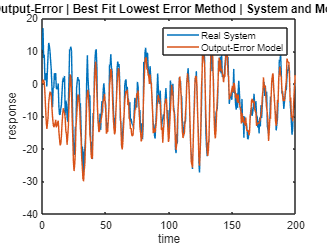

%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_1)
legend('Real System','Output-Error Model')
title(" System I : Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

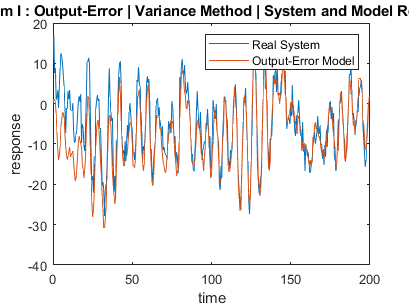


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_1)
legend('Real System','Output-Error Model')
title(" System I : Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

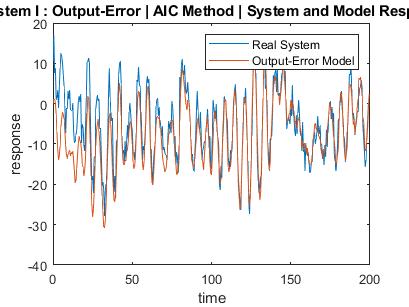


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_1)
legend('Real System','Output-Error Model')
title(" System I : Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

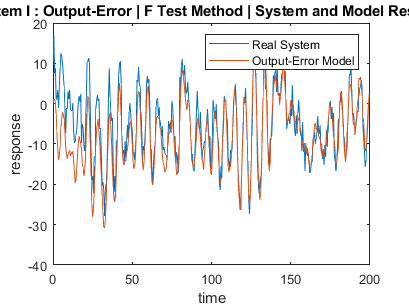


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_1)
legend('Real System','Output-Error Model')
title(" System I : Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

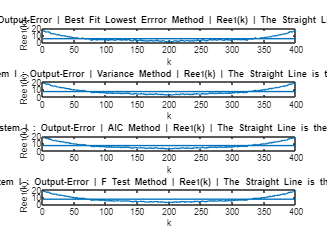

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Ree_1(2:end), 1:N_val-1, mean(oe_BestFit_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | Best Fit Lowest Errror Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Ree_1(2:end), 1:N_val-1, mean(oe_Var_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | Variance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Ree_1(2:end), 1:N_val-1, mean(oe_AIC_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | AIC Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Ree_1(2:end), 1:N_val-1, mean(oe_FTest_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | F Test Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Rue_1(2:end), 1:N_val-1, mean(oe_BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Rue_1(2:end), 1:N_val-1, mean(oe_Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Rue_1(2:end), 1:N_val-1, mean(oe_AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Rue_1(2:end), 1:N_val-1, mean(oe_FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" System I : Output-Error | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")





### System II

%%

% System Z2 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System II Identification Begins:------------------------------\n")

>>> System II Identification Begins:------------------------------


%%


Ts = 0.5; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data2 = iddata(y2,u2,Ts);



%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    try
        sys = oe(data2, [na nb nk]);
        oe_y_hat_2 = lsim(sys, u2, t);
    catch
        break
    end

    [r2_oe, mse_oe] = rSQR(y2, oe_y_hat_2);

    error = y2 - oe_y_hat_2;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.317572 | MSE=51.183366 | var=51.354548 | s_hat=30710.019542 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.670197 | MSE=24.735878 | var=24.901890 | s_hat=14841.526682 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.670196 | MSE=24.735894 | var=24.985752 | s_hat=14841.536471 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=-13.777812 | MSE=1108.364103 | var=1123.341996 | s_hat=665018.461700 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=-1940048505243.498291 | MSE=145507337193691.750000 | var=147973563247822.093750 | s_hat=87304402316215040.000000 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=-56827.906184 | MSE=4262276.325629 | var=4349261.556764 | s_hat=2557365795.377142 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=-30365186.495276 | MSE=2277446962.733490 | var=2331856958.430194 | s_hat=1366468177640.093506 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=-2979222.720253 | MSE=223447459.827155 | var=229569308.041597 | s_hat=134068475896.292648 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=-1095138.552643 | MSE=82137554.669262 | var=84677891.411610 | s_hat=49282532801.557053 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=-2218321776.944307 | MSE=166378363259.929382 | var=172115548199.926910 | s_hat=99827017955957.609375 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=-1788329461.544101 | MSE=134128119692.050644 | var=139233342240.883301 | s_hat=80476871815230.546875 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=-326212089.943712 | MSE=24466528844.660946 | var=25485967546.521835 | s_hat=14679917306796.576172 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=-1920873895155.508545 | MSE=144069204874789.218750 | var=150594987673995.750000 | s_hat=86441522924873552.000000 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=-12790038.697357 | MSE=959277365.454097 | var=1006234998.728073 | s_hat=575566419272.457764 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=-6059030020000415.000000 | MSE=454438804908020608.000000 | var=478356636745285184.000000 | s_hat=272663282944812548096.000000 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.025954 | MSE=73.055291 | var=77.171082 | s_hat=43833.174444 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=-2526799739.846607 | MSE=189514798685.904053 | var=200899079879.050476 | s_hat=113708879211542.562500 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=-1424689784.522457 | MSE=106854450524.317627 | var=113674947366.295288 | s_hat=64112670314590.539062 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=-19117432.783214 | MSE=1433843987.020127 | var=1530794292.192310 | s_hat=860306392212.078003 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.037563 | MSE=72.184639 | var=77.340685 | s_hat=43310.783423 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=-393564735.318411 | MSE=29518105676.338379 | var=31739898576.707920 | s_hat=17710863405803.019531 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=-28160598.193307 | MSE=2112098636.358818 | var=2279243132.761312 | s_hat=1267259181815.289551 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.678625 | MSE=24.103769 | var=26.105165 | s_hat=14462.261337 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.586645 | MSE=31.002393 | var=33.698253 | s_hat=18601.435838 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.073821 | MSE=69.465189 | var=75.780206 | s_hat=41679.113360 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.516430 | MSE=36.268658 | var=39.710210 | s_hat=21761.194966 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=-3.162287 | MSE=312.179480 | var=343.054374 | s_hat=187307.688286 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=-1.063848 | MSE=154.792501 | var=170.727023 | s_hat=92875.500445 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=-889056.950938 | MSE=66681041.583355 | var=73816651.199286 | s_hat=40008624950.012978 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=-0.472224 | MSE=110.419572 | var=122.688413 | s_hat=66251.743085 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=-6034552.783992 | MSE=452603040.535917 | var=504761755.244517 | s_hat=271561824321.550385 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.630419 | MSE=27.719270 | var=31.029034 | s_hat=16631.562020 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=-1.213716 | MSE=166.032888 | var=186.553806 | s_hat=99619.732578 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.659749 | MSE=25.519485 | var=28.781374 | s_hat=15311.690946 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.645153 | MSE=26.614181 | var=30.129261 | s_hat=15968.508365 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=-640846799.559899 | MSE=48064732013.912224 | var=54619013652.172958 | s_hat=28838839208347.320312 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=-228787541.875956 | MSE=17159501969.654324 | var=19573576391.240665 | s_hat=10295701181792.589844 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.276408 | MSE=54.270802 | var=62.142139 | s_hat=32562.480971 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=-49783445.349860 | MSE=3733853403.722093 | var=4291785521.519641 | s_hat=2240312042233.252441 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.591450 | MSE=30.642062 | var=35.356225 | s_hat=18385.237123 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.541623 | MSE=34.379178 | var=39.821442 | s_hat=20627.506744 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.640974 | MSE=26.927649 | var=31.311220 | s_hat=16156.589631 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=-1627230150.487433 | MSE=122045364177.316849 | var=142465405654.455292 | s_hat=73227218506390.015625 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=-90076928.252680 | MSE=6755941453.376260 | var=7917118890.675298 | s_hat=4053564872025.752441 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=-180240.538064 | MSE=13518459.040814 | var=15904069.459781 | s_hat=8111075424.488367 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=-113514527.203090 | MSE=8513806065.662397 | var=10055676455.506765 | s_hat=5108283639397.436523 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=-17330373.641059 | MSE=1299811143.779516 | var=1541278036.102192 | s_hat=779886686267.709229 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=-8005956906.307234 | MSE=600462033872.141479 | var=714835754609.692505 | s_hat=360277220323285.000000 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=-481974.451511 | MSE=36149077.898088 | var=43206069.200902 | s_hat=21689446738.852951 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=-7922204.716636 | MSE=594180534.874360 | var=713016641.849233 | s_hat=356508320924.616333 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=-286641843.986604 | MSE=21498684945.009323 | var=25902030054.228050 | s_hat=12899210967005.568359 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=-81616177.213821 | MSE=6121368992.432579 | var=7404881845.684588 | s_hat=3672821395459.555664 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=-1080988826.763225 | MSE=81076223320.578323 | var=98473145733.495972 | s_hat=48645733992347.007812 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=-9608799.696085 | MSE=720678374.346155 | var=878876066.275797 | s_hat=432407024607.692017 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=-468810769.945194 | MSE=35161701753.101250 | var=43055145003.797455 | s_hat=21097021051860.753906 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=-3283779.600339 | MSE=246289806.565106 | var=302815335.940704 | s_hat=147773883939.063416 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-1877716207.435246 | MSE=140832296077.264587 | var=173867032194.153595 | s_hat=84499377646358.640625 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=-3000391455.404192 | MSE=225035080401.278961 | var=278969107935.470093 | s_hat=135021048240767.515625 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=-226163921.374842 | MSE=16962725429.329741 | var=21115425845.638695 | s_hat=10177635257597.851562 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=-90208493.547610 | MSE=6765809101.365790 | var=8457261376.707239 | s_hat=4059485460819.474609 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=-40137899.711452 | MSE=3010419088.636194 | var=3778768730.505678 | s_hat=1806251453181.714111 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=-24545773.619024 | MSE=1840979900.510586 | var=2320562899.803261 | s_hat=1104587940306.352051 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=-4673590.712116 | MSE=350528290.051577 | var=443706696.267819 | s_hat=210316974030.946381 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=-1037270.398624 | MSE=77797332.774368 | var=98894914.543688 | s_hat=46678399664.620651 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 23 


na = bestFitDegree;
nb = bestFitDegree;
nk = 1;
p = na+nb;

BestFitModel_2 = oe(data2, [na nb nk])

BestFitModel_2 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = -20.91 z^-1 + 48.76 z^-2 - 87.54 z^-3 + 130.1 z^-4 - 145.6 z^-5 + 144.6 z^-6 - 115 z^-7          
          + 51.89 z^-8 + 15.66 z^-9 - 84.18 z^-10 + 136.6 z^-11 - 147.4 z^-12 + 134.4 z^-13 - 86.74 z^-14 
          + 14.94 z^-15 + 49.54 z^-16 - 112.1 z^-17 + 140.3 z^-18 - 139.9 z^-19 + 118.4 z^-20             
                                                            - 88.33 z^-21 + 40.16 z^-22 - 22.71 z^-23     
                                                                                                          
                                                                                                          
  F(z) = 1 - 0.9615 z^-1 + 1.453 z^-2 - 1.843 z^-3 + 1.909 z^-4 - 1.273 z^-5 + 0.6805 z^-6 + 0.1689 z^-7  
          - 0.6841 z

BestFit_y_hat_2 = lsim(BestFitModel_2, u2_val, t_val);
% [oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 2 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 2 


na = minVarIndex;
nb = minVarIndex;
nk = 1;
p = na+nb;

oe_VarModel_2 = oe(data2, [na nb nk])

oe_VarModel_2 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)
  B(z) = -0.4374 z^-1 + 1.703 z^-2                   
                                                     
  F(z) = 1 - 1.639 z^-1 + 0.8849 z^-2                
                                                     
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nf=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using OE on time domain data "data2".
Fit to estimation data: 42.57%                 
FPE: 25.07, MSE: 24.74                         


Var_y_hat_2 = lsim(oe_VarModel_2, u2_val, t_val);
% [oe_Var_r2, oe_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nk = 1;
p = na+nb;

oe_AICModel_2 = oe(data2, [na nb nk])

oe_AICModel_2 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)
  B(z) = -0.4374 z^-1 + 1.703 z^-2                   
                                                     
  F(z) = 1 - 1.639 z^-1 + 0.8849 z^-2                
                                                     
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nf=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using OE on time domain data "data2".
Fit to estimation data: 42.57%                 
FPE: 25.07, MSE: 24.74                         


AIC_y_hat_2 = lsim(oe_AICModel_2, u2_val, t_val);
% [oe_AIC_r2, oe_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.25 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nk = 1;
p = na+nb;

oe_FTestModel_2 = oe(data2, [na nb nk])

oe_FTestModel_2 =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)
  B(z) = -0.4374 z^-1 + 1.703 z^-2                   
                                                     
  F(z) = 1 - 1.639 z^-1 + 0.8849 z^-2                
                                                     
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nf=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using OE on time domain data "data2".
Fit to estimation data: 42.57%                 
FPE: 25.07, MSE: 24.74                         


FTest_y_hat_2 = lsim(oe_FTestModel_2, u2_val, t_val);
% [oe_FTest_r2, oe_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[oe_BestFit_r2_2, oe_BestFit_mse_2] = rSQR(y2_val, BestFit_y_hat_2);
[oe_Var_r2_2, oe_Var_mse_2] = rSQR(y2_val, Var_y_hat_2);
[oe_AIC_r2_2, oe_AIC_mse_2] = rSQR(y2_val, AIC_y_hat_2);
[oe_FTest_r2_2, oe_FTest_mse_2] = rSQR(y2_val, FTest_y_hat_2);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_BestFit_r2_2, oe_BestFit_mse_2)

    R2 value : 0.6609   | MSE : 29.9673 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Var_r2_2, oe_Var_mse_2)

    R2 value : 0.7021   | MSE : 26.3236 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Cov_r2, oe_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_AIC_r2_2, oe_AIC_mse_2)

    R2 value : 0.7021   | MSE : 26.3236 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_FTest_r2_2, oe_FTest_mse_2)

    R2 value : 0.7021   | MSE : 26.3236 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

oe_BestFitError_2 = y2_val - BestFit_y_hat_2;
oe_VarError_2 = y2_val - Var_y_hat_2;
oe_AICError_2 = y2_val - AIC_y_hat_2;
oe_FTestError_2 = y2_val - FTest_y_hat_2;

for k=0:N_val-1
    oe_BestFit_Ree_2(k+1,1) = AutoCorrelate(oe_BestFitError_2, k);
    oe_Var_Ree_2(k+1,1) = AutoCorrelate(oe_VarError_2, k);
    oe_AIC_Ree_2(k+1,1) = AutoCorrelate(oe_AICError_2, k);
    oe_FTest_Ree_2(k+1,1) = AutoCorrelate(oe_FTestError_2, k);
end

for k=0:N_val-1
    oe_BestFit_Rue_2(k+1,1) = CrossCorrelate(u2_val, oe_BestFitError_2, k);
    oe_Var_Rue_2(k+1,1) = CrossCorrelate(u2_val, oe_VarError_2, k);
    oe_AIC_Rue_2(k+1,1) = CrossCorrelate(u2_val, oe_AICError_2, k);
    oe_FTest_Rue_2(k+1,1) = CrossCorrelate(u2_val, oe_FTestError_2, k);
end


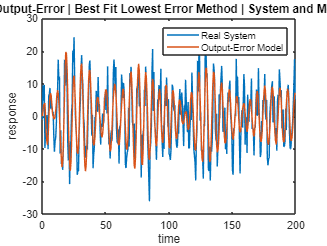


%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_2)
legend('Real System','Output-Error Model')
title(" System II : Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

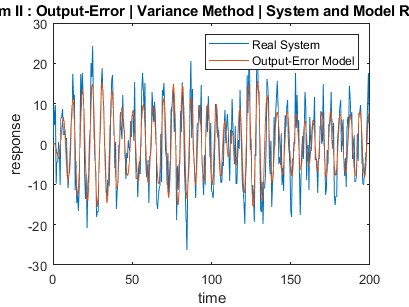


figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_2)
legend('Real System','Output-Error Model')
title(" System II : Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

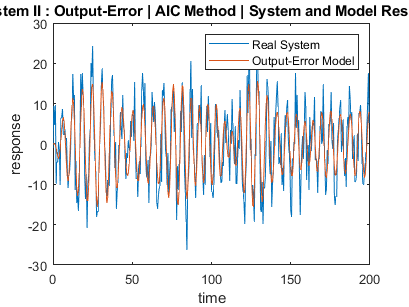


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_2)
legend('Real System','Output-Error Model')
title(" System II : Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

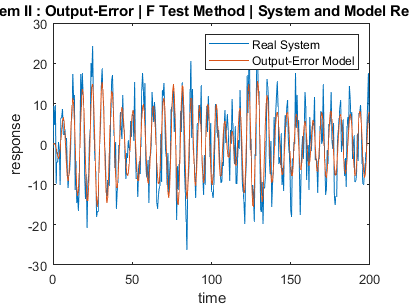


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_2)
legend('Real System','Output-Error Model')
title(" System II : Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

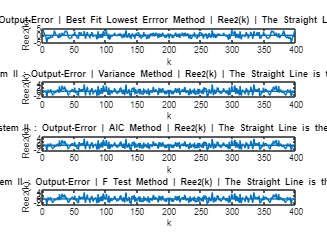


%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Ree_2(2:end), 1:N_val-1, mean(oe_BestFit_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | Best Fit Lowest Errror Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Ree_2(2:end), 1:N_val-1, mean(oe_Var_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | Variance Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Ree_2(2:end), 1:N_val-1, mean(oe_AIC_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | AIC Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Ree_2(2:end), 1:N_val-1, mean(oe_FTest_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | F Test Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_2(k)")

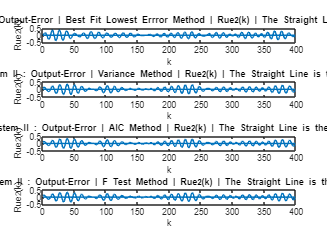


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,oe_BestFit_Rue_2(2:end), 1:N_val-1, mean(oe_BestFit_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | Best Fit Lowest Errror Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,2)
plot(1:N_val-1,oe_Var_Rue_2(2:end), 1:N_val-1, mean(oe_Var_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | Variance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,3)
plot(1:N_val-1,oe_AIC_Rue_2(2:end), 1:N_val-1, mean(oe_AIC_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | AIC Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(4,1,4)
plot(1:N_val-1,oe_FTest_Rue_2(2:end), 1:N_val-1, mean(oe_FTest_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" System II : Output-Error | F Test Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")